clear;
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


P_motor = K/((J*s+b) * (L*s+R) + K^2)

P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
연속시간 전달 함수입니다.
모델 속성


% (a)
zeta = 0.4;
wn = 20

wn = 20

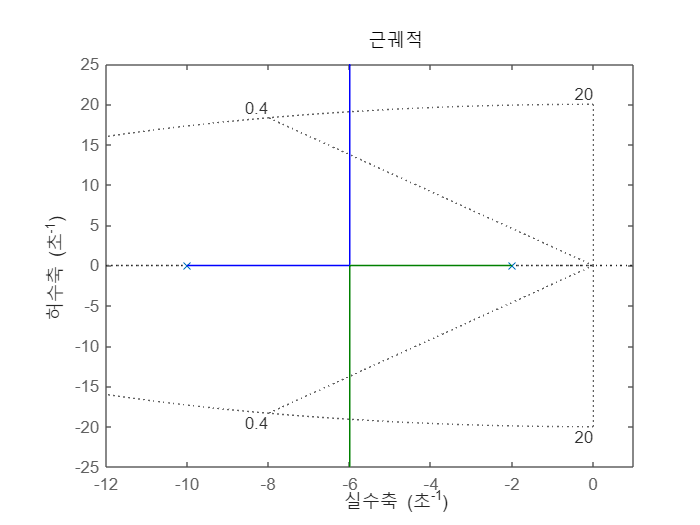

rlocus(P_motor)
sgrid(zeta,wn)
axis([-12 1 -25 25])

% (b)
root_real = -6 % x=-6 축을 기준으로 위아래로 뻗기 때문, root의 실수치

root_real = -6

theta = acos(zeta) % zeta = 0.4와 음의 x축과의 각도(rad)

theta = 1.1593

root_angle = pi-theta % zeta = 0.4와 양의x축과의 각도(rad)

root_angle = 1.9823

root_imag = 1i*root_real*tan(root_angle) % root의 허수치

root_imag = 0.0000 +13.7477i

root = root_real + root_imag

root = -6.0000 +13.7477i

k = rlocfind(P_motor,root) % k는 충분히 커서 조건을 만족하지만, 계속 풀어보겠다.

k = 102.4900


alpha = 20/dcgain(P_motor*k)

alpha = 1.9534


z0 = -0.1 %다수가 쓰는 값

z0 = -0.1000

p0 = z0/alpha

p0 = -0.0512


C_lag = (s - z0)/(s - p0) % kv가 없는 보상기

C_lag =
 
    s + 0.1
  -----------
  s + 0.05119
 
연속시간 전달 함수입니다.
모델 속성


kv = dcgain(C_lag*P_motor*k)

kv = 20

C_lag = k*C_lag % kv가 있는 보상기

C_lag =
 
  102.5 s + 10.25
  ---------------
    s + 0.05119
 
연속시간 전달 함수입니다.
모델 속성


dcgain(P_motor*C_lag)

ans = 20.0000

% (c)
PO = 100*exp(-zeta*pi/sqrt(1-zeta^2)) %overshoot이 25%를 넘으면 안 된다.

PO = 25.3827

T = feedback(P_motor*C_lag,1)

T =
 
               1.025 s + 0.1025
  ------------------------------------------
  0.005 s^3 + 0.06026 s^2 + 1.128 s + 0.1076
 
연속시간 전달 함수입니다.
모델 속성


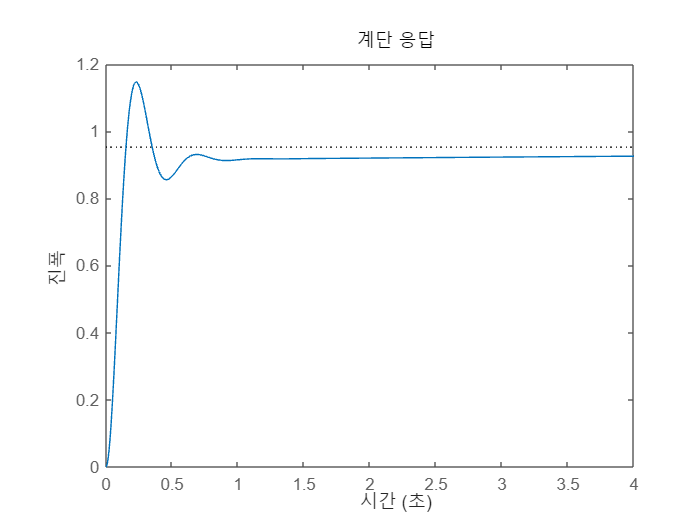

step(T)

stepinfo(T) %overshoot이 20 으로 조건에 만족

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.1024
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.8554
      SettlingMax: 1.1464
        Overshoot: 20.3716
       Undershoot: 0
             Peak: 1.1464
         PeakTime: 0.2311


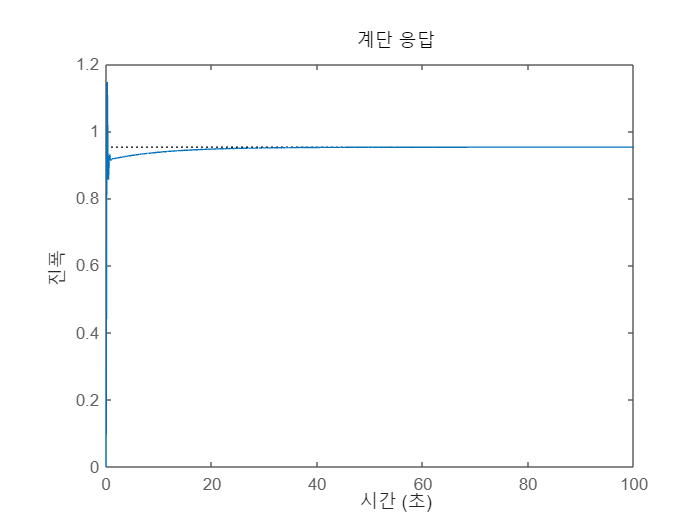


%time info에서는 보이지 않으니 시간을 100s 까지 돌려보면 정상상태오차가 5%보다 약간 작음을 볼 수 있다.
step(T,100)

y = step(T,100)

y =          0
    0.0228
    0.0849
    0.1767
    0.2888
    0.4122
    0.5392
    0.6630
    0.7781
    0.8804


y(numel(y)) % t = 100s 일 때의 y이다. 정상상태오차가 5%보다 작다.

ans = 0.9524